# Example: Basic Solver for Acoustics in 1D

This live-script features the following:

- 1D example

- how to set up acoustic sources using functions

- setup and how to run basic acoustic solver

- different visualizations

- plot for medium parameters

- animate for solutions

- animateMedBack for solutions

- plotTimeSeries for solutions

Acoustic equations: 


$$\frac{\partial p}{\partial t} + \kappa \frac{\partial v}{\partial x} = f_p$$



$$\frac{\partial v}{\partial t} + \beta \frac{\partial p}{\partial x} = f_v$$


assuming zero-pressure at boundaries, and initial conditions provided by user.

First, the computational spatial grid is defined and used to initialize the grid space for the pressure fields.

clear

domain_x = [0,1]; 
domain_t = [0.,0.7];

% Computational grids and grid spaces
Nx       = 401; %number of spatial grid points
grid_x   = Grid1DUnifPrimal(domain_x,Nx);
gridSp_P = GridSpace1D(grid_x); %grid space for pressure
dx       = gridSp_P.h; %spatial grid size

Second, medium parameters are specified as a continuous function

- $\kappa(x)$ is the bulk modulus

- $\beta(x)$ is the buoyancy (reciprocal of density)

The function sampleMedium samples the acoustic medium parameters over a specified grid space. A staggered FDM is assumed, and thus the buoyancy will be sampled over the appropriate staggered/dual grid space.

The sample function also compute the wave speed, $c = \sqrt{\kappa \beta}$, and the maximum wave speed $c_{\rm max}$ required to compute an appropriate time step-size $\Delta_t$. 

The medium parameters are sampled for plotting purposes.

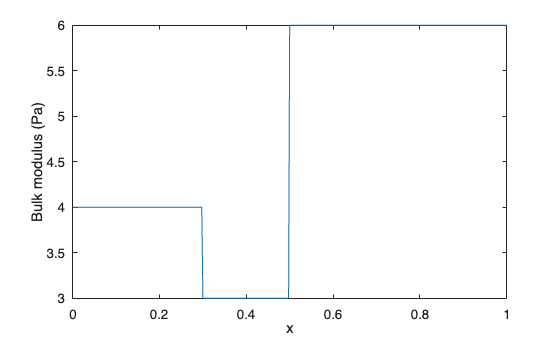

% Acoustic medium parameters
% medium = AcousticMedium1D.constant(KappaValue=1,BetaValue=1);
medium = AcousticMedium1D.layered( ...
    BetaValues=[0.25,0.5,1], ...
    KappaValues=[4,3,6], ...
    Domain=domain_x, ...
    RelativeWidths=[0.3,0.2,0.5]);

[kappa,beta,wspeed,cMax] = sampleMedium1D(gridSp_P,medium); %sampled on grids

kappa.plot;

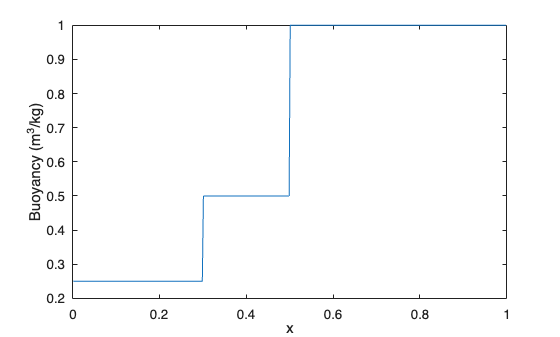

beta.plot;

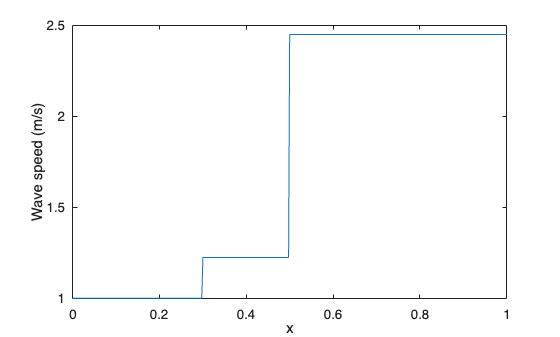

wspeed.plot;

Unlike the spatial grid, we store the temporal grid as a simple array of time points.

For the 2-4 staggered FD scheme in 1D, we take $\Delta_t$ such that 

$\Delta_t \le \frac{6}{7} \frac{\Delta_x}{c_{\rm max}}$.

When computing $\Delta_t$, it is important to ensure that the computational time interval is divisible by the step-size. Usually this requires a recomputation of $\Delta_t$ as done so here.

% Time grid (computed after medium)
CFL_factor = 0.9;
dt = CFL_factor*(6/7)*dx/cMax; %CFL condition for 2-4 FDM
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing to ensure time domain divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

These next couple of steps can be done in no particular order.

Here we specify the out spatial grid and time points. In this example we sample the entire spatial and temporal domains, though in practice we may only be interested in a small collection of spatial points.

% Output spatial grid and time points
gsp_out   = GridSpace1D(Grid1DUnifPrimal(domain_x,101));
t_pts_out = linspace(domain_t(1),domain_t(2),51);

Here we specify an acoustic source in the pressure equation only. In particular, it is assumed that the source is separable, that is, of the form 


$$f_p(x,t) = p(x)q(t)$$
 

for some specified $p(x)$ and $q(t)$. In this example we have


$$p(x) = \exp\left(  - \frac{(x-0.35)^2}{0.04^2} \right)$$



$$q(t) = \exp\left(-\frac{(t-0.12)^2}{0.025^2} \right)$$


% Acoustic source
source = AcousticSource1D( ...
    @(x) exp(-((x-0.35)/0.04).^2), ...
    @(t) exp(-((t-0.12)/0.025).^2));

Here we specify the initial conditions functions such that


$$p(x,0) = p_0(x)$$



$$v(x,0) = v_0(x)$$


% Initial data
p0 = @(x) zeros(size(x));
v0 = @(x) zeros(size(x));

Before running the solver, we must initialize it using the computational grid space and time points, output grid space and time points, and medium parameters.

% Initializing solver
solver = AcousticSolver1DStaggered( ...
    gridSp_P,t_pts, ...
    gsp_out,t_pts_out, ...
    medium, ...
    SpatialOrder=4);

To run the solver, we make use of the `solve()` method, and input the initial conditions, along with the acoustic source.

The outputs/solutions are of type `GridFunctionTimeSeries`.

% Running solver
[P,V] = solver.solve(p0,v0,Source=source);

Objects of type `GridFunctionTimeSeries` class method `obj.animate()` for visualizing solutions as grid functions vs x, animated over time.

The `obj.animate()` method is recommended when visualizing the time evolution of the full grid function.

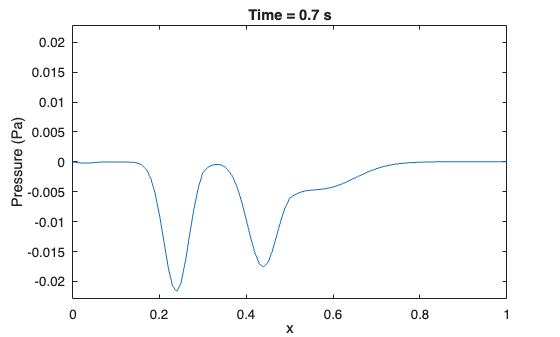

P.animate;

Another option for visualization is the method obj`.animateMedBack()`, which is similar to obj`.animate()` but it also plots the wave speed in the background. 

The obj`.animateMedBack()` method is recommended for visualizing the effects of acoustic media, in particular reflections due to medium discontinuities.

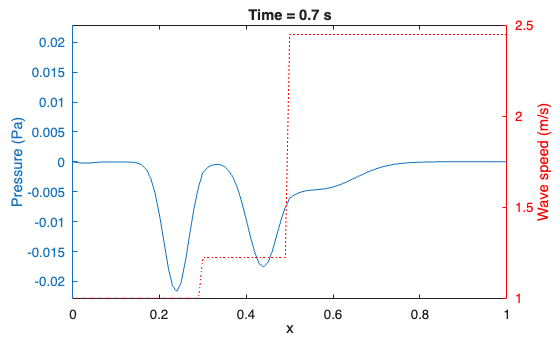

P.animateMedBack(medium);

Another option for visualization is the method obj`.plotTimeSeries()`, which plots the receiver index versus time. Each point in the output grid is interpreted as a receiver and indexed.

The obj`.plotTimeSeries()` method is recommended for visualizing data as a time series.

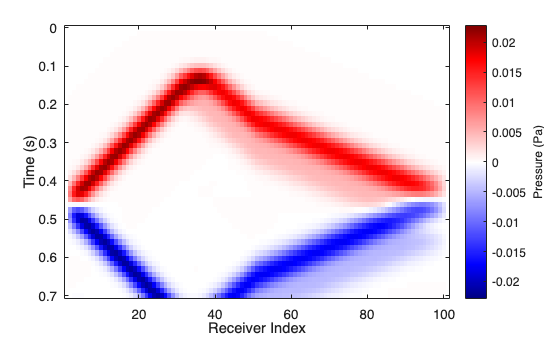

P.plotTimeSeries;